## The Aligning Torque Caused by the Kingpin Inclination

The existence of the kingpin inclination makes the steering system work against the front axle load when steering and makes the steered wheel return to the center automatically as well. The corresponding aligning torque can be expressed as:

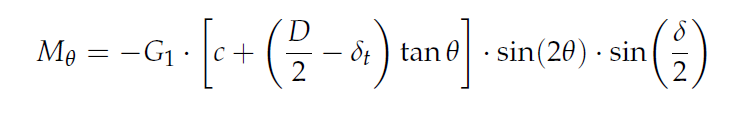

**For calculation of dt, refere steering_friction_torque.mlx**

ct = 1.15; % For Bias or 1.5 for radial
B = 17.78; % Width of the tire in cm
kt = 0.015*B + 0.42;
Fz = 20; % Vertical Load on the tire in unit 10 N.
D = 292.12; % Diameter in cm
P = 300 % Pressure in unit kPa
s = 0.557;
t = 122.7
e = 2.71828;
c = 0.2 % kingpin offset in cm

dt = ct*kt*((Fz^0.85)/((B^0.7)*(D^0.43)*(P^0.6)));


**Final Calculations:**

G1 = 21; % Front axle load
theta = 2; % Kingpin inclination
omega = 22; % Steered wheel angle.

steering_friction_torque = -G1 * (c + (D/2 - dt)* tand (theta))*sind(2*theta)*sin(omega/2);
